# **demo09 of Im2mesh Tool**

demo09 - Demonstrate how to select phases for meshing

Author: Jiexian Ma

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-meshes](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-meshes)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function im2mesh use a mesh generator called MESH2D. We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Phases

Let's start demo. Import image Phases.tif.

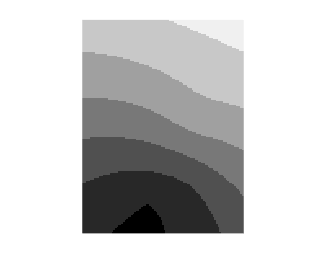

im = imread("Phases.tif");
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Show the grayscale levels in the image.

intensity = unique( im ); 
intensity'

ans = 1×7 uint8 row vector
     0    40    80   120   160   200   240


There're 7phases. Let's generate mesh using the default setting.

[ vert, tria, tnum ] = im2mesh( im );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          2                 69                 98
          8                 84                162


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                122                 98
         10                140                592
         11                140                594


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                142                588
          8                  6                588



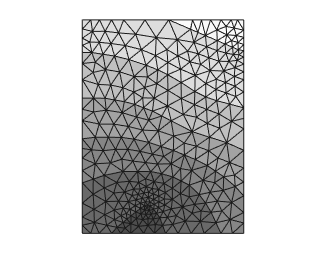

plotMeshes( vert, tria, tnum )

## Select phases for meshing

However, we don't need some of the phases in the image. Those phases may be air voids or background. We don't want them to show up in the finite element meshes.

Function im2mesh support phase selection for meshing. We need to assign a index vector to opt.select_phase. I'll show you how to do that. 

We knew that the image has the following grayscales.

intensity'

ans = 1×7 uint8 row vector
     0    40    80   120   160   200   240


For example, we are interested in the grayscale: 40, 80, 120, 200, 240. We don't want grayscle of 0 and 160. Let's use the following operation to obtain the index vector for opt.select_phase.

grayscale_we_like = [ 40, 80, 120, 200, 240 ]';
ind_vec = find( ismember(intensity, grayscale_we_like) );

% ind_vec is the index vector we need
ind_vec'

ans =      2     3     4     6     7


Let's generate mesh.

opt = [];                       % reset opt
opt.select_phase = ind_vec;     % assign index vector to opt.select_phase
[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          2                 65                 73
          8                 78                123


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                110                 73
         10                127                451
         11                127                455


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                103                451
          8                 21                451



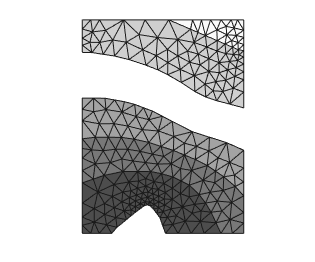

plotMeshes( vert, tria, tnum )

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo